# TCLab Cascade Control

**Objective**: Design, tune, and test a cascade controller for the temperature control lab.

## **Design**

**Design** a cascade controller by labeling a block diagram that includes the inner and outer control loops. A standard feedback control system includes only one measurement (*T2*) and one actuator (*Q1*) that is adjusted to meet the setpoint (*T2,SP*).

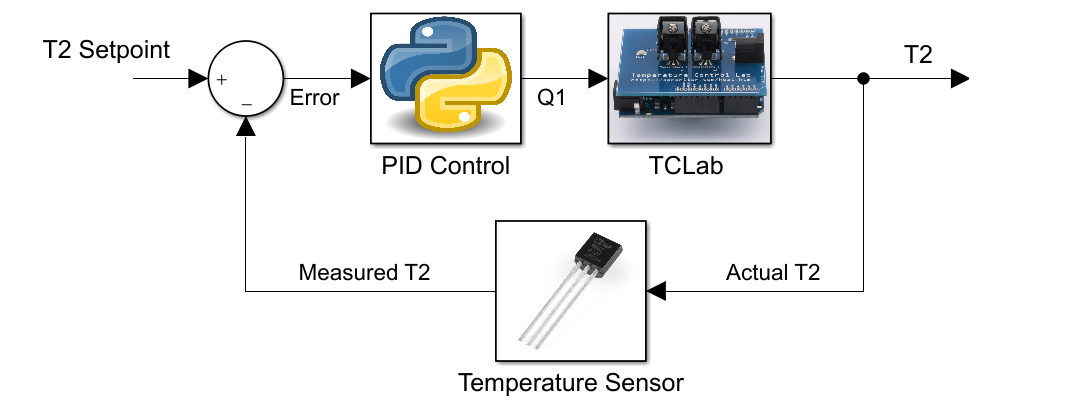

With cascade control, the inner loop is a $T_1$ controller that has $Q_1$ as the controller output. The outer loop is a $T_2$ controller that has $T_{1, SP}$ as the controller output. The solution is included at the bottom of this livescript.

## **Tune**

**Tune** the cascade controller with the TCLab to meet a temperature 2 (*T**2*) target set point by adjusting heater 1 (*Q**1*). Minimize the integral absolute error (IAE) while staying below 85oC for temperature 1 (*T**1*). Compare the cascade control performance with a standard PI controller.

### Standard PI Control

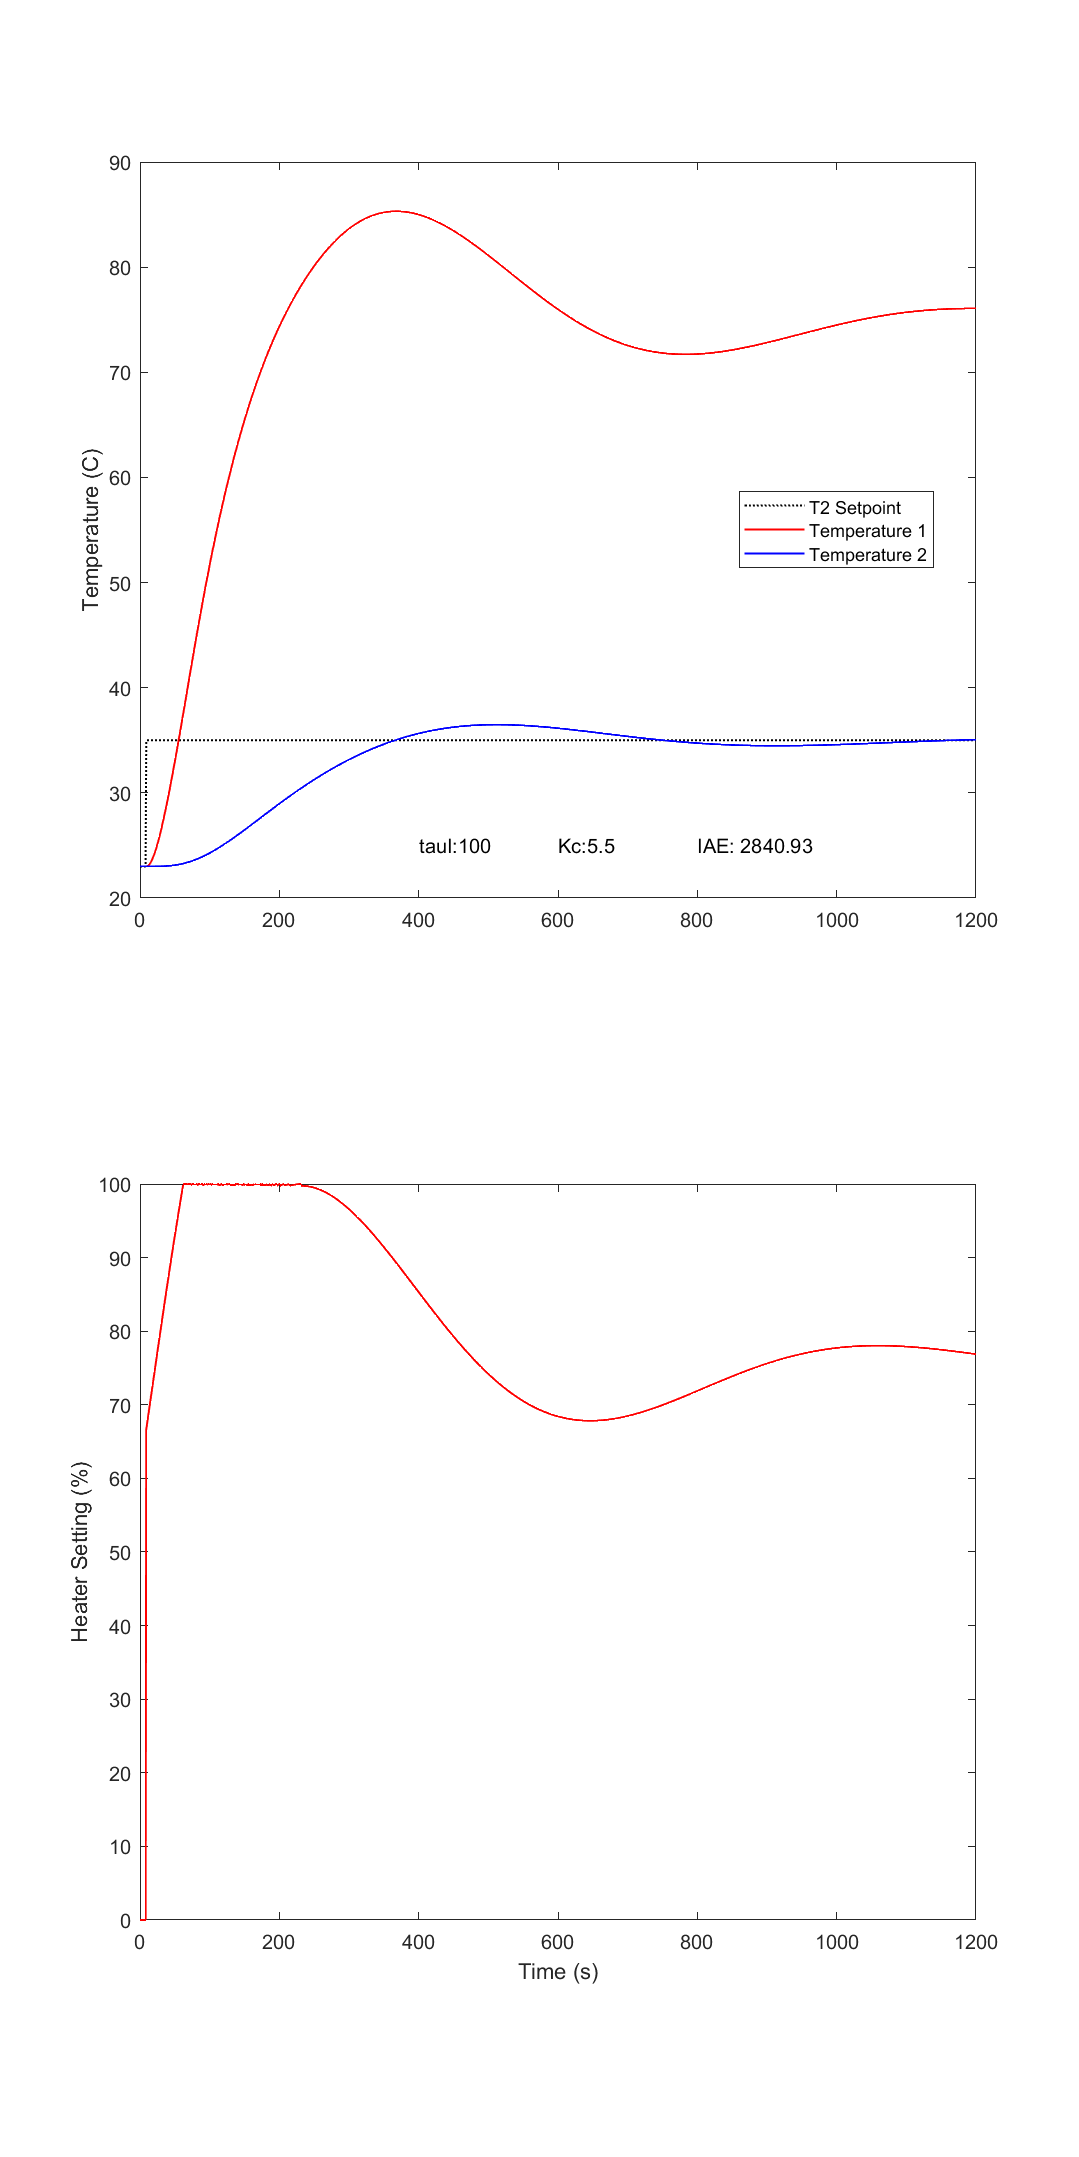

Kc1 = 0;
tauI1 = 0;
Kc2 = 5.5;
tauI2 = 100;
pidPlot(Kc1, tauI1, Kc2, tauI2)

### Cascade Control

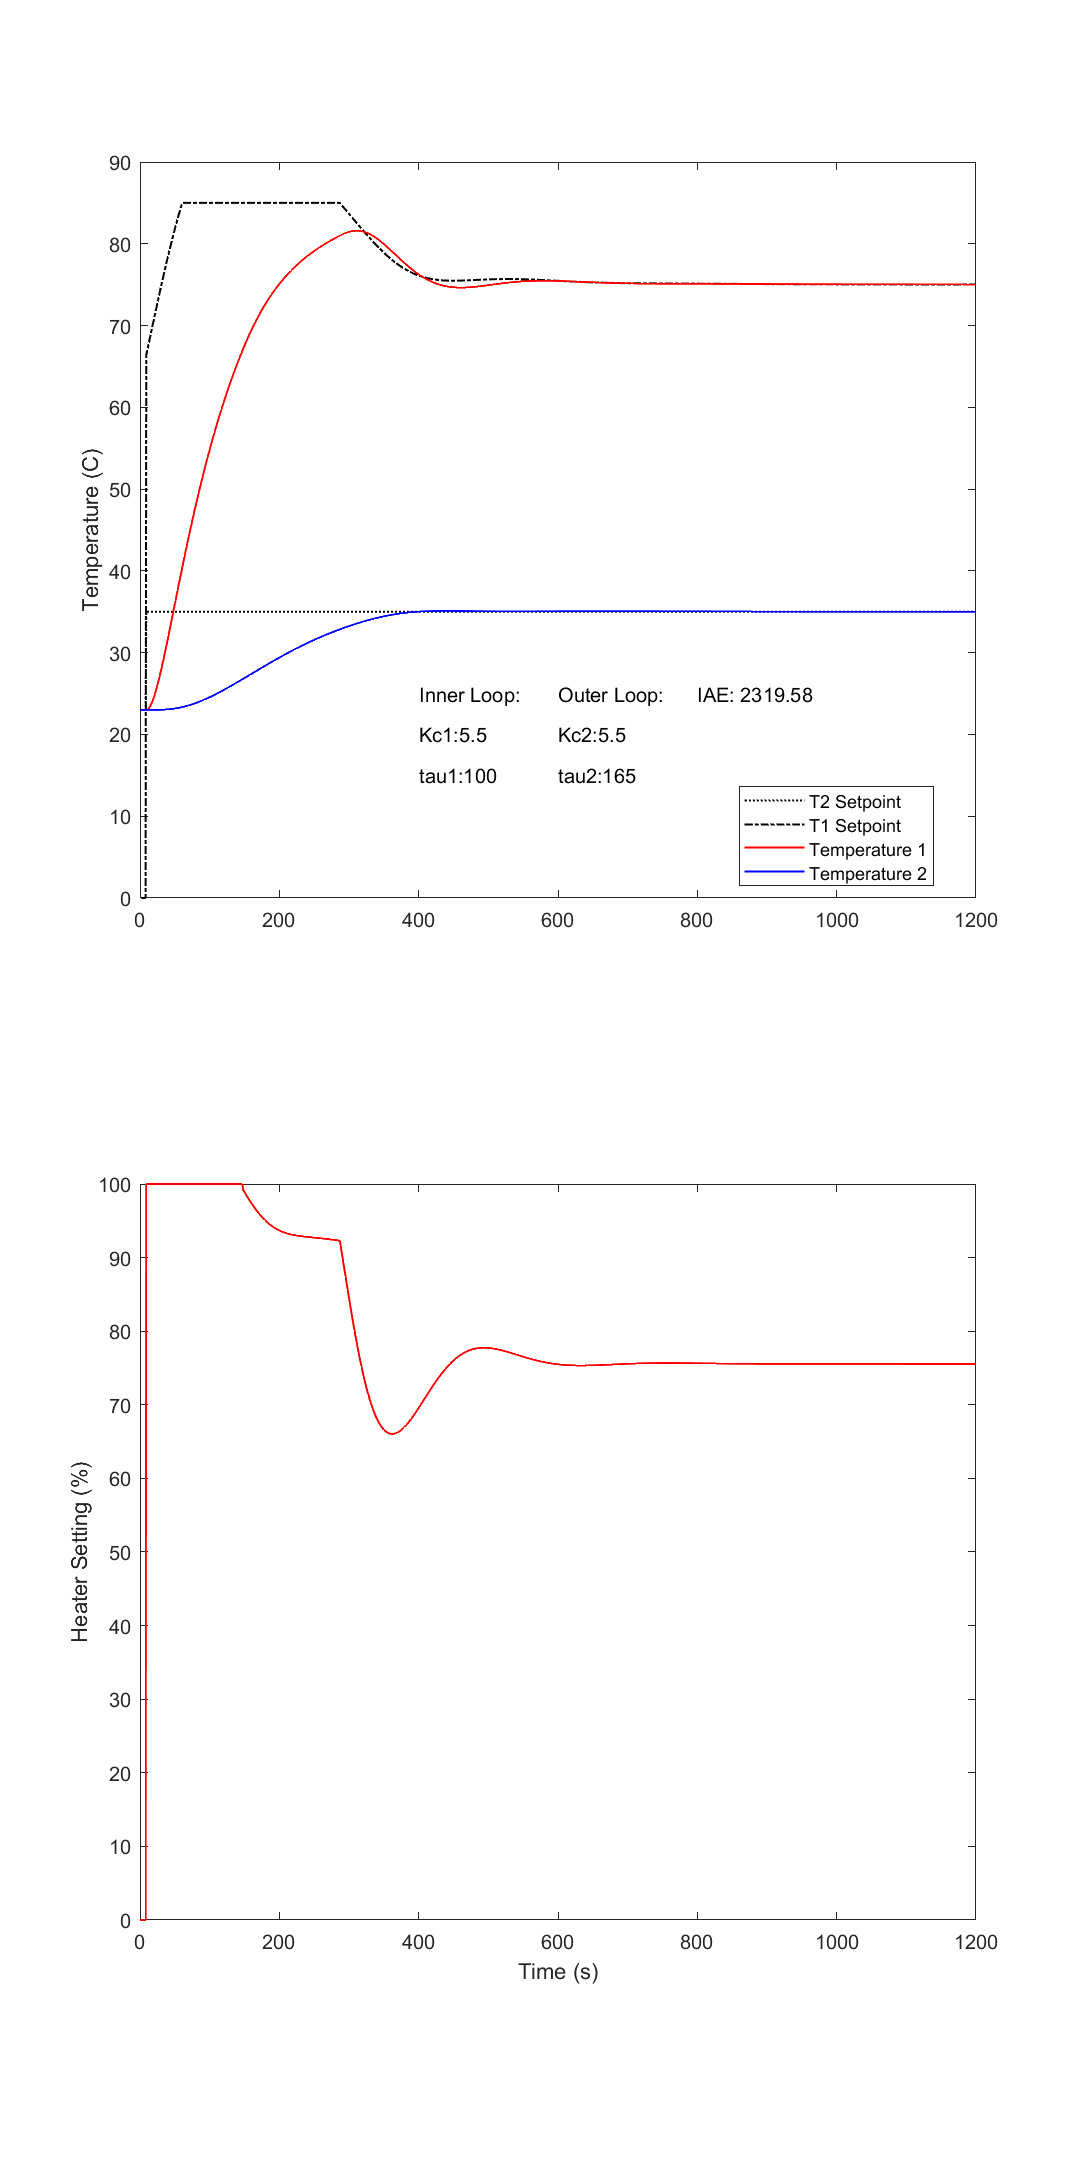

Kc1 = 5.5;
tauI1 = 100;
Kc2 = 5.5;
tauI2 = 165;
pidPlot(Kc1, tauI1, Kc2, tauI2)

## Test

**Test** the cascade control on the TCLab. Discuss any differences between the simulated and measured values.

% PID Parameters
Kc1   = 5.0;
tauI1 = 50.0; % sec
Kc2   = 3.0;
tauI2 = 100.0; % sec
coeffs = [Kc1 tauI1 Kc2 tauI2];

lab = tclab()

lab =   tclab with properties:

      device: 'TCLab'
       board: 'Leonardo'
    platform: 'matlab'
         lab: [1×1 arduino]



% Run time in minutes
run_time = 15.0;

% Number of cycles
loops = int32(60.0*run_time);
tm = zeros(loops, 1);

% Heater set point steps
Tsp1 = ones(loops, 1) * lab.T1;
Tsp2 = ones(loops, 1) * lab.T2;
Tsp2(10:end) = 35.0;        % step up

T1 = ones(loops, 1) * lab.T1; % measured T (degC)
T2 = ones(loops, 1) * lab.T2; % measured T (degC)

% impulse tests (0 - 100%)
Q1 = ones(loops, 1) * 0.0;
Q2 = ones(loops, 1) * 0.0;

% Main Loop
start_time = 0;
tic
prev_time = toc;
dt_error = 0.0;
% Integral error
ierr1 = 0.0;
ierr2 = 0.0;
% Integral absolute error
iae = 0.0;

figure()
try
    for i = 2:loops
        while toc < prev_time+1
            pause(0.01)
        end

        % Record time and change in time
        t = toc;
        dt = t - prev_time;

        prev_time = t;
        tm(i) = toc;

        % Read temperatures in Kelvin
        T1(i) = lab.T1;
        T2(i) = lab.T2;

        % Disturbances
        d1 = T1(i) - 23.0;
        d2 = T2(i) - 23.0;

        % Integral absolute error
        iae = iae + abs(Tsp2(i)-T2(i));

        % Calculate PID output pidController(sp, pv, ierr, dt, d, coeffs, cid)
        [Tsp1(i),P,ierr2] = pidController(Tsp2(i),T2(i),ierr2,dt,d1,coeffs,2);
        [Q1(i),P,ierr1] = pidController(Tsp1(i),T1(i),ierr1,dt,d2,coeffs,1);

        % Write output (0-100)
        lab.Q1(Q1(i));
        lab.Q2(0);

        % Update plot       
        subplot(2,1,1)
        plot(tm(1:i),Tsp1(1:i),'k--','DisplayName', '$T_1$ set point')
        hold on
        plot(tm(1:i),T1(1:i),'r.','DisplayName', '$T_1$ measured')
        hold on
        plot(tm(1:i),Tsp2(1:i),'k-','DisplayName', '$T_2$ set point')
        hold on
        plot(tm(1:i),T2(1:i),'b.','DisplayName', '$T_2$ measured')
        hold off
        ylabel('Temperature (C)')
        text(tm(i),23,'IAE: ' + string(round(iae,2)))
        legend('Location',"best", 'Interpreter',"latex")
        subplot(2,1,2)
        plot(tm(1:i),Q1(1:i),'b-','DisplayName', '$Q_1$')
        ylabel('Heater (%)')
        legend('Location',"best", 'Interpreter',"latex")
        xlabel('Time (sec)')
    end

catch
    lab.off
    clear lab
end
        

function dZdt = process(~, z, u, constants)
    % unpack z
    x1 = z(1);
    y1 = z(2);
    x2 = z(3);
    y2 = z(4);
    
    % unpack constants
    Kp = constants(1);
    Kd = constants(2);
    taus = constants(3);
    zeta = constants(4);
    thetap = constants(5);
    
    % calculate derivatives
    dx1dt = (1.0/(taus^2)) * (-2.0*zeta*taus*x1-(y1-23.0) + Kp*u + Kd*(y2-y1));
    dy1dt = x1;
    dx2dt = (1.0/(taus^2)) * (-2.0*zeta*taus*x2-(y2-23.0) + Kd*(y1-y2));
    dy2dt = x2;
    
    % return derivatives in z
    dZdt = [dx1dt;dy1dt;dx2dt;dy2dt];
end

function pidPlot(Kc1, tauI1, Kc2, tauI2)
    tf = 1200;
    n = 1201;
    
    tm_ = linspace(0,tf,n);    % create time vector
    P1_ = zeros(n, 1);         % initialize proportional term
    I1_ = zeros(n, 1);         % initialize integral term
    P2_ = zeros(n, 1);         % initialize proportional term
    I2_ = zeros(n, 1);         % initialize integral term
    e1_ = zeros(n, 1);         % initialize error
    ie1_ = zeros(n, 1);        % initialize integral error
    e2_ = zeros(n, 1);         % initialize error
    ie2_ = zeros(n, 1);        % initialize integral error
    OP_ = zeros(n, 1);         % initialize controller output
    PV1_ = ones(n, 1)*23.0;    % initialize process variable
    PV2_ = ones(n, 1)*23.0;    % initialize process variable
    SP1_ = ones(n, 1)*23.0;    % initialize setpoint
    SP2_ = ones(n, 1)*23.0;    % initialize setpoint
    SP2_(10:end) = 35.0;       % step up
    z0 = [0,23.0,0,23.0];      % initial condition
    
    % TCLab Second Order Constants
    Kp = 0.8473;
    Kd = 0.3;
    taus = 51.08;
    zeta = 1.581;
    thetap = 0.0;
    constants = [Kp, Kd, taus, zeta, thetap];
    
    for i=2:n
        ts = [tm_(i-1) tm_(i)];
        [~, Z] = ode45(@(t, z) process(t, z, OP_(i-1), constants), ts, z0);
        z0 = Z(end, :);
        dt = ts(2) - ts(1);
        
        if Kc1 == 0 && tauI1 == 0
            PV1_(i) = z0(2);
            PV2_(i) = z0(4);
            
            e2_(i) = SP2_(i) - PV2_(i);
            ie2_(i) = e2_(i) * dt + ie2_(i-1);
            
            P2_(i) = Kc2 * e2_(i);
            I2_(i) = Kc2 / tauI2 * ie2_(i);
            OP_(i) = min(100, max(0, P2_(i) + I2_(i)));
            if OP_(i)==100 || OP_(i) == 0
                ie2_(i) = ie2_(i-1);
            end
            
        else
            % outer loop
            PV2_(i) = z0(4);
            e2_(i) = SP2_(i) - PV2_(i);
            ie2_(i) = e2_(i) * dt + ie2_(i-1);
            P2_(i) = Kc2 * e2_(i);
            I2_(i) = Kc2 / tauI2 * ie2_(i);
            SP1_(i) = min(85, max(0, P2_(i)+I2_(i)));
            if SP1_(i)==100 || SP1_(i) == 0
                ie2_(i) = ie2_(i-1);
            end
            
            % inner loop
            PV1_(i) = z0(2);
            e1_(i) = SP1_(i) - PV1_(i);
            ie1_(i) = e1_(i) * dt + ie1_(i-1);
            P1_(i) = Kc1 * e1_(i);
            I1_(i) = Kc1 / tauI1 * ie1_(i);
            OP_(i) = min(100, max(0, P1_(i) + I1_(i)));
            if OP_(i)==100 || OP_(i) == 0
                ie1_(i) = ie1_(i-1);
            end
        end
    end
    % Plot solution
    figure()
    subplot(2, 1, 1)
    plot(tm_, SP2_, 'K:', 'LineWidth',1, 'DisplayName','T2 Setpoint')
    hold on
    if Kc1 ~= 0 && tauI1 ~= 0
        plot(tm_(3:end), SP1_(3:end), 'K-.', 'LineWidth',1, 'DisplayName','T1 Setpoint')
        hold on
        IAE = sum(abs(SP2_ - PV2_));
        text(800, 25, 'IAE: '+string(round(IAE, 2)))
        text(400, 25, 'Inner Loop:')
        text(400, 20, 'Kc1:' + string(Kc1))
        text(400, 15, 'tau1:' + string(tauI1))
        text(600, 25, 'Outer Loop:')
        text(600, 20, 'Kc2:' + string(Kc2))
        text(600, 15, 'tau2:' + string(tauI2))
    else
        IAE = sum(abs(SP2_ - PV2_));
        text(800, 25, 'IAE: '+string(round(IAE, 2)))
        text(600, 25, 'Kc:' + string(Kc2))
        text(400, 25, 'tauI:' + string(tauI2))
        
    end
    plot(tm_, PV1_, 'r-', 'LineWidth', 1, 'DisplayName', 'Temperature 1')
    hold on
    plot(tm_, PV2_, 'b-', 'LineWidth', 1, 'DisplayName', 'Temperature 2')
    hold off
    legend("Location","best")
    ylabel('Temperature (C)')
    subplot(2, 1, 2)
    plot(tm_, OP_, 'r-','LineWidth',1)
    ylabel('Heater Setting (%)')
    xlabel('Time (s)')
    set(gcf,'position',[0,0,1200,2400]);
    
end

function [op, P, I] = pidController(sp, pv, ierr, dt, d, coeffs, cid)
    Kc1 = coeffs(1);
    tauI1 = coeffs(2);
    Kc2 = coeffs(3);
    tauI2 = coeffs(4);

    if cid == 1
        KP = Kc1;
        KI = Kc1 / tauI1;
        ophi = 100;
        oplo = 0;
    else
        KP = Kc2;
        KI = Kc2/tauI2;
        ophi = 85;
        oplo = 23;
    end
    % ubias for controller (initial heater)
    op0 = 0;
    % calculate the error
    error = sp-pv;
    % calculate the integral error
    ierr = ierr + KI * error * dt;
    % calculate the PID output
    P = KP * error;
    I = ierr;
    op = op0 + P + I;
    % implement anti-reset windup
    if op < oplo || op > ophi
        I = I - KI * error * dt;
        % clip output
        op = max(oplo,min(ophi,op));
    end
end

## Solutions

### Design

By adding the second measurement ($T_1$) and another PID controller with ($T_{1, SP}$) as the inner loop, cascade control is implemented.

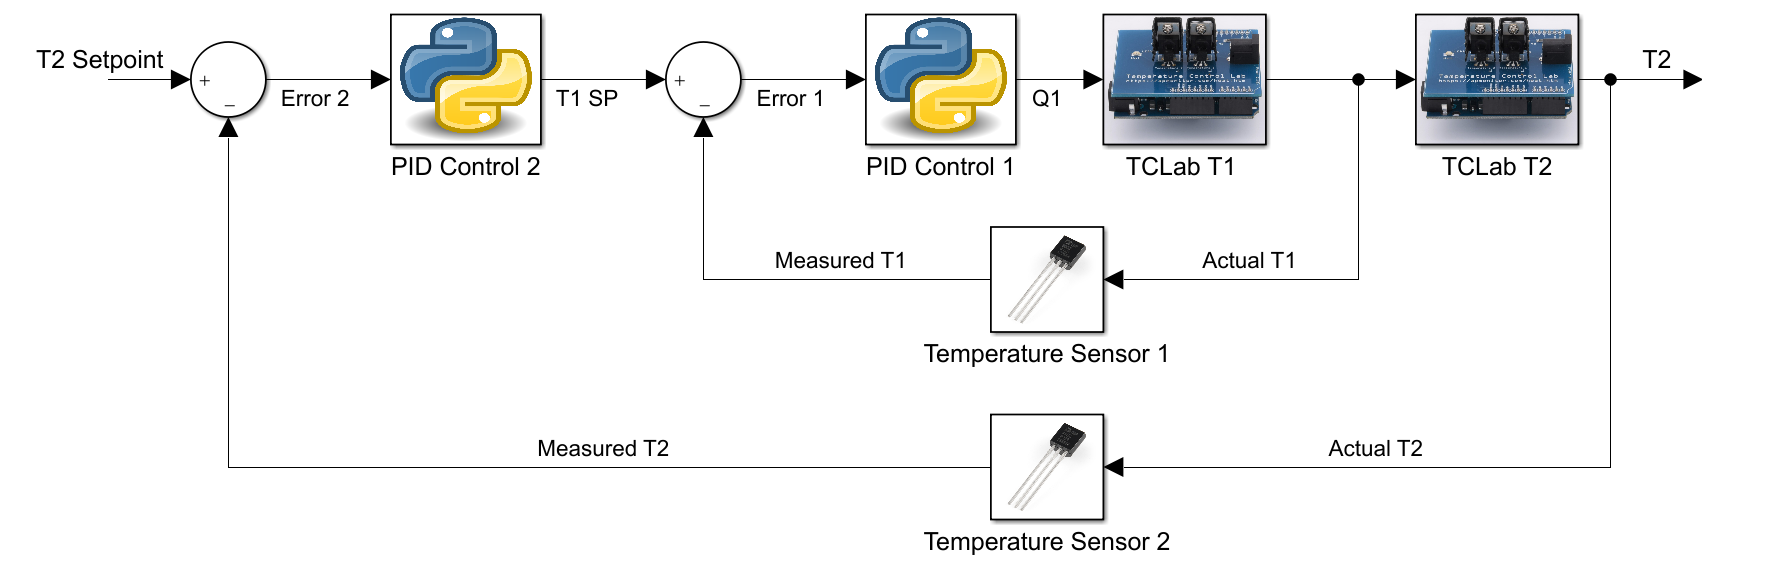

### Tune

Tuning the cascade controller involves minimizing the integral absolute error ($IAE$) while staying below $85^\circ\text{C}$ for temperature 1 ($T_1$). The controller output ($T_{1, SP}$) from the outer controller ($T_2$) is set to $85^\circ \text{C}$ to avoid overshooting the upper limit constraint. The anticipated cascade performance is $IAE=2319.58$  with $K_{c1}=5.5$, $\tau_{I1}=100$, $K_{c2}=5.5$, and $\tau_{I2}=165$.

### Test

The 15 minute test gives a larger IAE by about 8% ((2537.8-2345.2)/2345.2) than predicted because of unmodeled disturbances that are not included in the simulation. This is evident from the $Q_1$ adjustments even after $T_2$ reaches the setpoint.